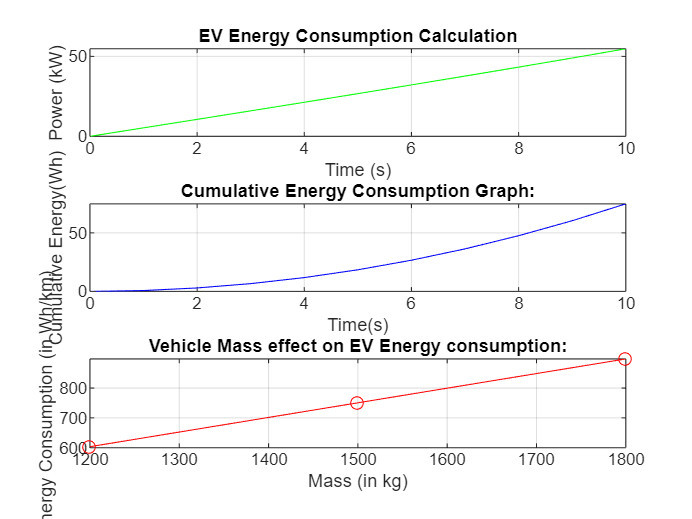

clc;       %clears command window
clear;     %clears workspace variables
close all; %closes all figures

%% PART ONE:

%% Vehicle Parameters
m = 1800;   %Vehicle mass in kg
g = 9.81;   %Gravity in m/s^2
Crr = 0.01; %Rolling resistance coefficient
rho = 1.225;%Air density in kg/m^3
Cd = 0.29;  %Drag coefficient
A = 2.2;    %Frontal area in m^2

%% Time Settings
t = 0:1:10; %time in seconds from 0 to 10 (step=1s) | vector creation

%MATLAB loves vectors

%% Speed Profile
v_kmph = linspace(0,60,length(t));  %Speed in kmph
v = v_kmph / 3.6;                   %Velocity in m/s (3.6 = conversion from kmph to m/s)

%% Compute Acceleration (Numerical Method)
% a = dv/dt;

dt = t(2) - t(1);   %Time step
a = diff(v)/dt;     %diff() is numerical differentiation. Also diff() reduces the vector length 

% When using numerical differentiation in MATLAB, acceleration must be divided by the time step to preserve physical correctness.
% Reducing the acceleration time increases vehicle acceleration, which increases tractive force demand. Since power is the product of force and velocity, the peak power requirement increases significantly for shorter acceleration times.
a(end+1) = a(end);  %Fixes the reducing vector length prob with this code line

%% Compute all Forces (Vectorized)
Frr = m*g*Crr;                %Rolling resistance force (constant)
Faero = 0.5*rho*Cd*A.*v.^2;   %Aerodynamic force (vector)
Facc = m.*a;                  %Acceleration (Inertial) Force

%**Note**: .* is element-wise multiplication and .^ is element-wise square 

%% Power Calculation
Ftotal = Frr+Faero+Facc;   %Total tractive force
P = Ftotal.*v;             %Power Demand (W)

%% Graph Plot between Time(s) and Power(kW)
figure;
subplot(3,1,1);
plot(t, P/1000, LineWidth=0.5,Color="g");
xlabel('Time (s)');
ylabel('Power (kW)');
title('EV Energy Consumption Calculation');
grid on;
hold on;

%% PART TWO:

%% Energy Calculation (1Wh = 3600J)
E_J = trapz(t, P);    %Energy in Joules; Trapezoidal numerical integration of Time and Power data
E_Wh = E_J/3600;      %Conversion of Energy from Joules to Watt-hour

%% Distance Calculation
dist_m = trapz(t, v);    %Distance in m
dist_km = dist_m / 1000; %Distance converted from m to km

%% Energy Consumption
E_Wh_per_km = E_Wh/dist_km; %Energy consumption in Wh/km


%% Energy vs Time Plot
E_ce = cumtrapz(t, P)/3600;    %Cumulative energy calculation using cumulative trapezoidal numerical integration

subplot(3,1,2)
plot(t, E_ce, 'LineWidth',0.5,'Color','b');
xlabel('Time(s)');
ylabel('Cumulative Energy(Wh)');
title('Cumulative Energy Consumption Graph:');
grid on;
hold on;

%% PART THREE:

%% Parameteric Sensitivity Analysis
mass_arr = [1200, 1500, 1800];                   %Masses in kg

%Never grow arrays inside the loop, preallocate it.
%Hence:

E_Wh_per_km_arr = zeros(length(mass_arr),1);     %zeros(length(x),n) has been used to make the code run faster, as the zeros means that it preallocate the zeros initially to estimate the required space for the values.


%% Loop Over Mass Values
for i = 1:length(mass_arr)         

    m = mass_arr(i);               %Updating the mass values (in kg)

    %Forces
    Frr = m*g*Crr;               
    Faero = 0.5*rho*Cd*A.*v.^2;   
    Facc = m.*a;
    Ftotal = Frr+Faero+Facc;

    %Power Calculation
    P = Ftotal.*v;

    %Energy Consumption in Joules
    E_Wh = trapz(t, P)/3600;

    %Distance Travelled in kms
    dist_km = trapz(t, v)/1000;

    %Energy Consumption in Wh/km
    E_Wh_per_km_arr(i) = E_Wh/dist_km;
end

%% Plotting the Sensitivity

subplot(3,1,3);
plot(mass_arr, E_Wh_per_km_arr, '-o', 'LineWidth',0.5,'Color','r');
xlabel('Mass (in kg)');
ylabel('Energy Consumption (in Wh/km)');
title('Vehicle Mass effect on EV Energy consumption:');
grid on;

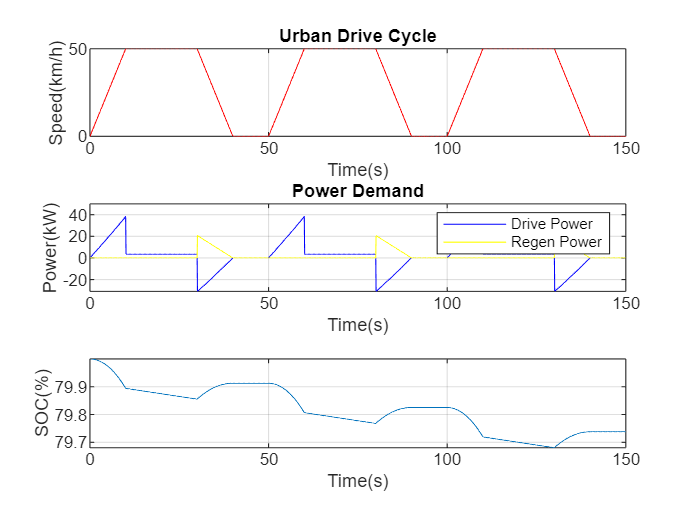


%% Definfing the Urban-Drive Cycle
dt = 0.1;                                   %Time step in s
t = 0:dt:150;                               %Time from 0 to 150s with dt amount of time step
v = zeros(size(t));                         %Velocity with preallocation

for i=1:length(t)
    tau = mod(t(i),50);                     %mod is used to reset the time after every end of the drive cycle (50s)

    if tau <= 10                            %Acceleration Phase
        v(i) = (50/3.6)*(tau/10);           %Velocity time relation or linear acceleration (v=vmax*(current time/total accel time))
                                            %(50/3.6) is to convert from km/h to m/s and (tau/10) is to normalized the time 0 to 1
    elseif tau <= 30                        %Cruising Phase
        v(i) = (50/3.6);
    elseif tau <= 40                        %Deceleration Phase
        v(i) = (50/3.6)*(1-(tau-30)/10);    %(tau-30): time since braking started
                                            %Divided by 10 to normalize the braking time
                                            %1-(.....): speed reduces from 1 to 0
    else 
        v(i) = 0;                           %Vehicle stops
    end

end

%% Acceleration, Forces and Power
a = [0 diff(v)/dt];

Frr = m*g*Crr;
Faero = 0.5*rho*Cd*A.*v.^2;
Facc = m.*a;

Ftotal = Frr+Faero+Facc;

P = Ftotal.*v;               %Mechanical Power (W)

E_Wh = trapz(t, P)/3600;

dist_km = trapz(t, v)/1000;

E_Wh_per_km_arr(i) = E_Wh/dist_km;

%% Urban Drive Cycle & Power Demand Graph Plots:
figure;

subplot(3,1,1)
plot(t, v*3.6, 'Color','r');
xlabel('Time(s)');
ylabel('Speed(km/h)');
title('Urban Drive Cycle');
grid on;
hold on;

%% PART FIVE:

%% Regenerative Braking Efficiency
regen_eff = 0.6; % 60% regen efficiency
P_regen_max = 30000; %30kW max regen Power

%% Core Logic of Regen Power Model
P_regen = zeros(size(P));

for i = 1:length(P)
    if a(i) < 0                                  % Deceleration only; Changed the Regen Physics logic from if P(i) < 0 to if a(i) < 0, because to ensure the regen physics the condition should be, **if accel is less than 0 or in negaitve which shows braking. This is more precise than previous to get precise results of SOC after regen.**
        P_inertia = m * a(i) * v(i);             % Inertial braking power

        if P_inertia < 0
            P_regen(i) = min(abs(P_inertia) * regen_eff, P_regen_max);
        end
    end
end
P_drive = P;                                                        %Assuming the values of P are 0 if they are less than 0
P_drive(P_drive < 0) = 0;


%% Battery Model: SOC Tracking
Batt_capacity = 50000;                      %50kWh
SOC = zeros(size(t));
SOC(1) = 0.8;                               % 80% initial SOC

for i = 2:length(t)
    E_drive = P_drive(i)*dt/3600;                 %Energy = Power x Time
    E_regen = P_regen(i)*dt/3600;           

    SOC(i) = SOC(i-1)...                    %States previous battery state, it starts from where the battery was in the last step
        -E_drive / Batt_capacity...         %This converts the energy used to the fraction of battery, reduces SOC
        +E_regen / Batt_capacity;         %This converts the recoverd energy and adds back to the battery, SOC increases
end


subplot(3,1,2);
plot(t, P/1000, 'Color','b');
hold on;
plot(t,P_regen/1000, 'Color','y');
xlabel('Time(s)');
ylabel('Power(kW)');
legend('Drive Power', 'Regen Power');
title('Power Demand');
grid on;
hold on;


subplot(3,1,3);
plot(t, SOC*100);
xlabel('Time(s)');
ylabel('SOC(%)');
grid on;


%% Displaying all the required results:

fprintf('\n===== FINAL NUMERICAL RESULTS =====\n');


===== FINAL NUMERICAL RESULTS =====



fprintf('1. Total Energy Consumed (Urban Cycle): %.2f Wh\n', E_Wh);

1. Total Energy Consumed (Urban Cycle): 86.02 Wh


fprintf('2. Total Distance Travelled (Urban Cycle): %.3f km\n', dist_km);

2. Total Distance Travelled (Urban Cycle): 1.250 km


fprintf('3. Specific Energy Consumption: %.2f Wh/km\n', E_Wh/dist_km);

3. Specific Energy Consumption: 68.81 Wh/km



fprintf('4. Maximum Drive Power Demand: %.2f kW\n', max(P)/1000);

4. Maximum Drive Power Demand: 38.22 kW


fprintf('5. Maximum Braking Power (Mechanical): %.2f kW\n', min(P)/1000);

5. Maximum Braking Power (Mechanical): -30.93 kW



fprintf('6. Maximum Available Regen Power (before cap): %.2f W\n', ...
        max(abs(P(P<0)) * regen_eff));

6. Maximum Available Regen Power (before cap): 18558.70 W



fprintf('7. Maximum Regen Power Limit: %.2f W\n', P_regen_max);

7. Maximum Regen Power Limit: 30000.00 W



fprintf('8. Initial Battery SOC: %.2f %%\n', SOC(1)*100);

8. Initial Battery SOC: 80.00 %


fprintf('9. Final Battery SOC: %.2f %%\n', SOC(end)*100);

9. Final Battery SOC: 79.74 %



fprintf('10. Net SOC Change: %.4f %%\n', (SOC(end)-SOC(1))*100);

10. Net SOC Change: -0.2621 %


fprintf('==================================\n');


%% Correct Regen Energy & Regen Percentage Calculation

% Total regenerated electrical energy (Wh)
E_regen_total = trapz(t, P_regen) / 3600;

% Total mechanical braking energy available (Wh)
E_brake_mech = trapz(t, abs(min(P,0))) / 3600;

% Regeneration effectiveness (% of braking energy recovered)
regen_percentage = (E_regen_total / E_brake_mech) * 100;

fprintf('Total Regenerated Energy: %.2f Wh\n', E_regen_total);

Total Regenerated Energy: 85.94 Wh


fprintf('Regeneration Percentage: %.2f %%\n', regen_percentage);

Regeneration Percentage: 65.61 %
